
current=pwd;
folder='\data_7_class';
DatasetPath = strcat(current,folder);


imds = imageDatastore(DatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
%labelCount = countEachLabel(imds)

img = readimage(imds,1);
%size(img)

numTrainPercent = .75;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainPercent,'randomize');

inputSize = lgraph.Layers(1).InputSize;


pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter,'ColorPreprocessing','gray2rgb');

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation,'ColorPreprocessing','gray2rgb');

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

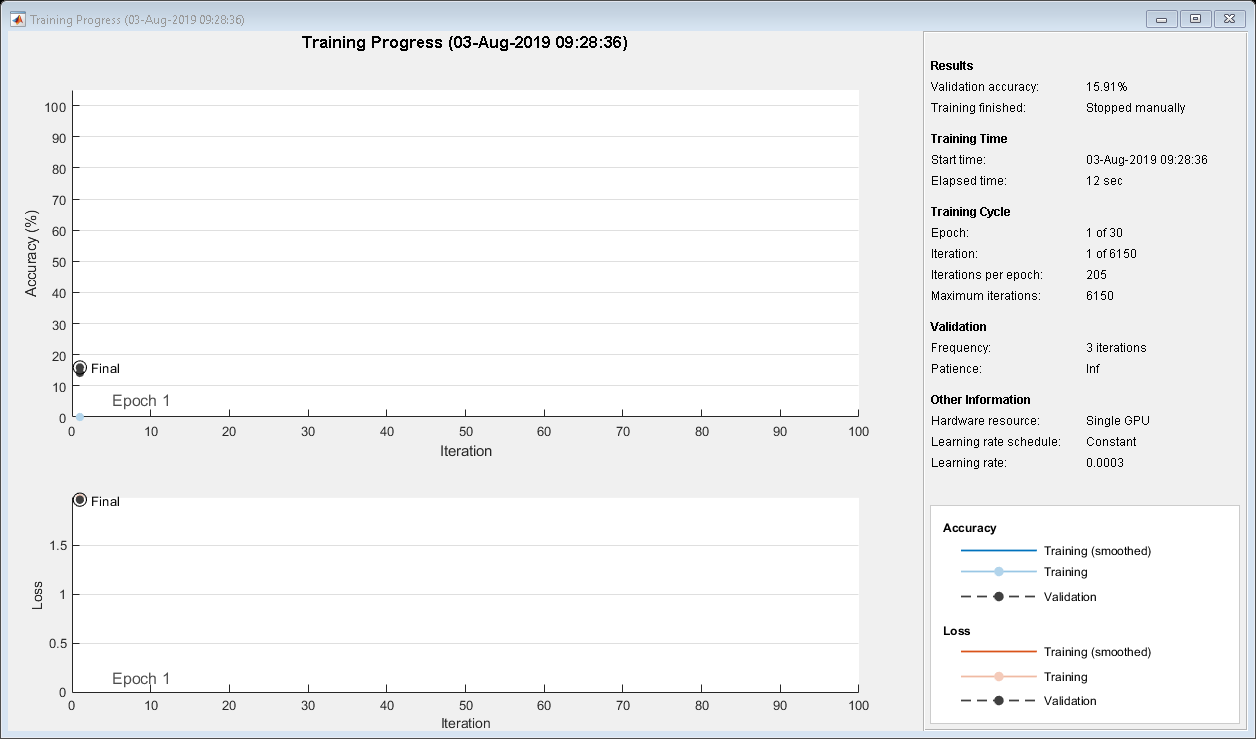

net = trainNetwork(augimdsTrain,lgraph,options);

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.1591